DSP Laboratory Report #2

Instructor: M.H. Shammakhi

Student: Dina Soltani Tehrani - 9523703

Last Update: Apr 6th

clc;
clear;

## part 2-1-b

The input is a rect signal and the output seems reasonable as it looks like a triangulare signal, which is the itegral of a rect signal.

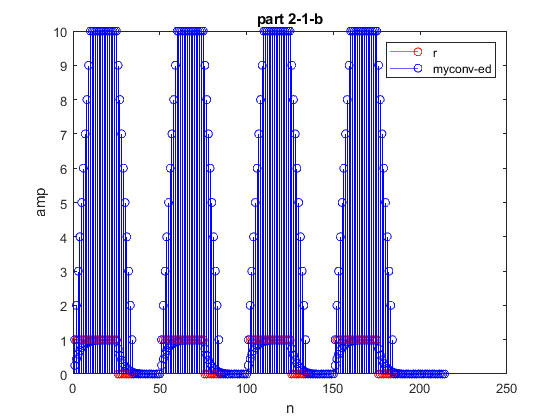

clc;
clear;
h1=ones(1,10); % filter #1
r = [ones(1,25) zeros(1,25) ones(1,25) zeros(1,25) ones(1,25) zeros(1,25) ones(1,25) zeros(1,25)];  
out= myconv(h1,r);
%--
figure(1)
stem(r,'r');
hold on
stem(out,'b')
legend('r','myconv-ed')
xlabel('n');
ylabel('amp');
title('part 2-1-b');

## part 2-1-c

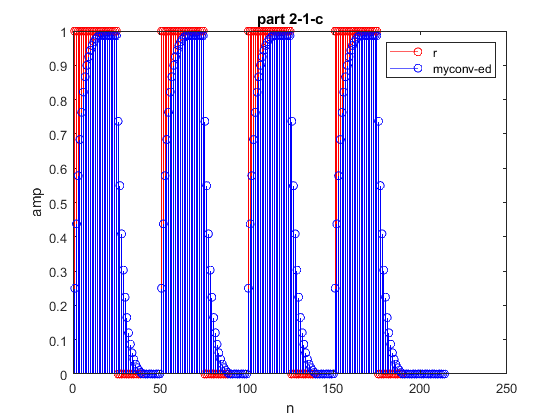


h2 = ones(1,15);
for n = 1:15
    h2(n) = 0.25*((0.75)^(n-1));
end
out= myconv(h2,r);
%--
figure(2)
stem(r,'r');
hold on
stem(out,'b')
legend('r','myconv-ed')
xlabel('n');
ylabel('amp');
title('part 2-1-c');

## part 2-1-d

We are experiencing singularities regarding to the jumps.

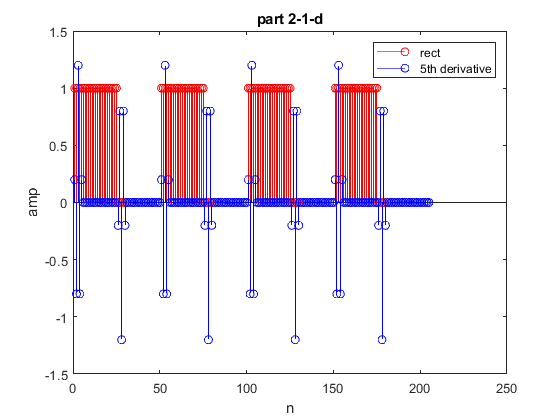


h3 = 1/5*[1 -5 10 -10 5 -1];
out= myconv(h3,r);
%--
figure(3)
stem(r,'r');
hold on
stem(out,'b')
legend('rect','5th derivative')
xlabel('n');
ylabel('amp');
title('part 2-1-d');

## part 2-2-a Noisy Signal Filtering

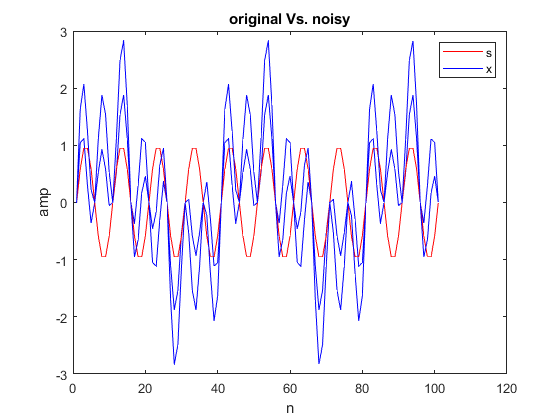


w1=0.05*pi; w2=0.2*pi; w3=0.35*pi; wa=0.15*pi; wb=0.25*pi;
n = 0:100;
s = sin(w2*n);
v = sin(w1*n)+sin(w3*n);
x = s+v;
%--
figure(4)
plot(s,'r');
hold on
plot(x,'b');
legend('s','x')
xlabel('n');
ylabel('amp');
title('original Vs. noisy');

## part 2-2-b

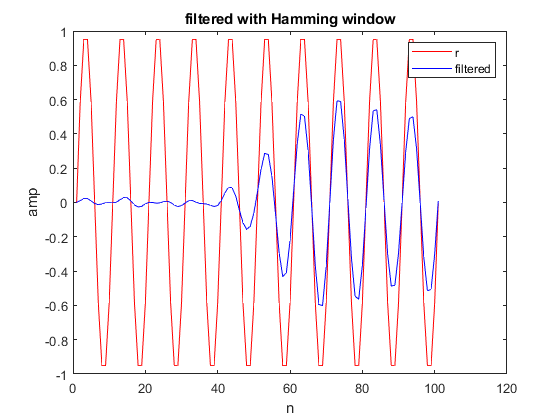


M=100;
w = zeros(1,M+1);
for ii = 1:M+1
    w(1, ii) = 0.54-0.46*sin(2*pi*(ii-1)/100);
end
h4 = w.*((wb/pi)*sinc((wb/pi)*(n-50))- (wa/pi)*sinc((wa/pi)*(n-50)));
out = filter(h4,1,x);

figure(5)
plot(s,'r');
hold on 
plot(out,'b');
legend('r','filtered')
xlabel('n');
ylabel('amp');
title('filtered with Hamming window');

## part 2-2-c

When entering Ap=0 dB, it appeared:

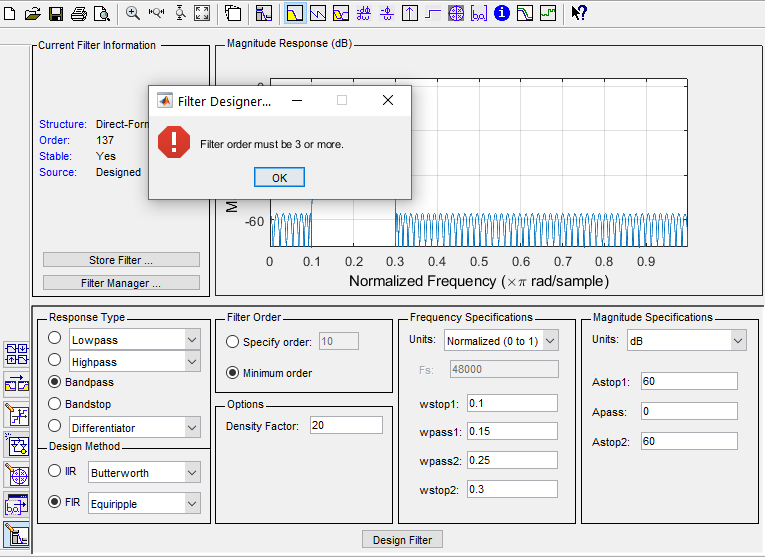

Therefore, I entered Ap=0.1 dB. However, the filter failed working properly.

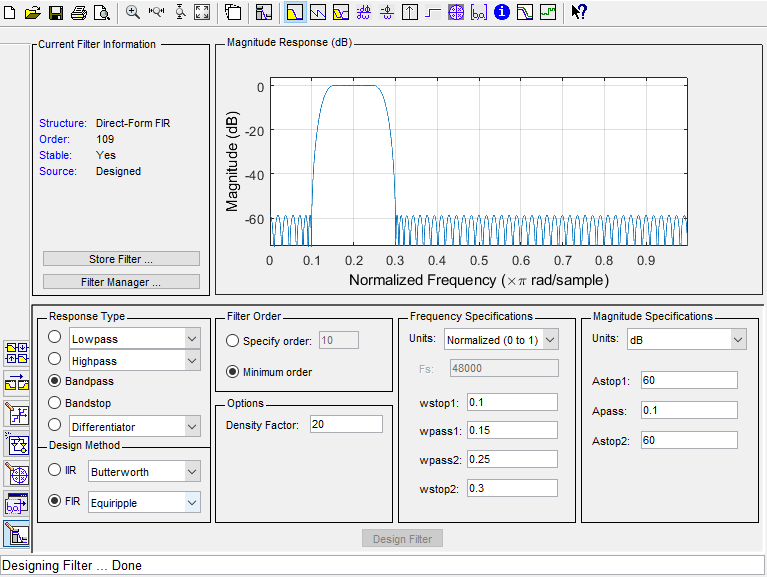

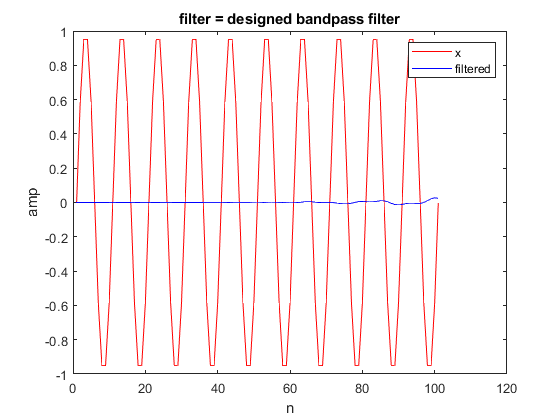


h5=load('bandpass.mat');
h5 = h5.bandpass;
out =filter(h5,1,x);
%--
figure(6)
plot(s,'r');
hold on 
plot(out,'b');
legend('x','filtered')
xlabel('n');
ylabel('amp');
title('filter = designed bandpass filter');

fprintf('Not the desired output with the metioned filter \n')

Not the desired output with the metioned filter 


## part 2-3 Voice Scrambling

At first, the voice was smooth and something like The Titanic melody. When scrambled, the sound was somewhat different. It appeared to be the same as before when we reconstructed the voice.

x2 = audioread('Audio01.wav');
x2=x2';
fprintf('original sound \n')

original sound 


% sound(x2);
%--
h = load('filter.mat');
h = h.filter;
n = 0:length(x2)-1;
s = 2*cos(2*pi*(12000/48000)*n);
out_01 = filter(h,1,x2);
out_11 = out_01.*s;
out_21 = filter(h,1,out_11);
fprintf('filtered sound \n')

filtered sound 


% sound(out_21,44000);
%--
out_22= filter(h,1,out_21);
out_12= out_22.*s;
out_02= filter(h,1,out_12);
fprintf('di-filtered sound \n')

di-filtered sound 


% sound(out_02,44000);

## part 3-1

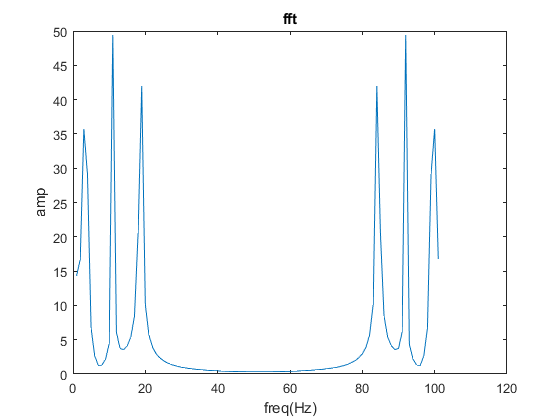

f0=100; fs=500;
t = 0:1/fs:2;
x_1 = sin(2*pi*f0*t);
x_2 = chirp(t,400,1,200);
x_3 = 50*[zeros(1,249) 1 zeros(1,751)];
x3 = x_1 + x_2 + x_3;
figure(7);
plot(abs(fft(x)));
xlabel('freq(Hz)');
ylabel('amp');
title('fft');

## part 3-2

In the Discrete Fourier, the signal is plotted assuming to be stationary. On the other case, the signal is plotted, assuming to be non-stationary. Therefore, we can see the changes in frequency with the time. The shorter the length of the window, the more accurate the outcome.

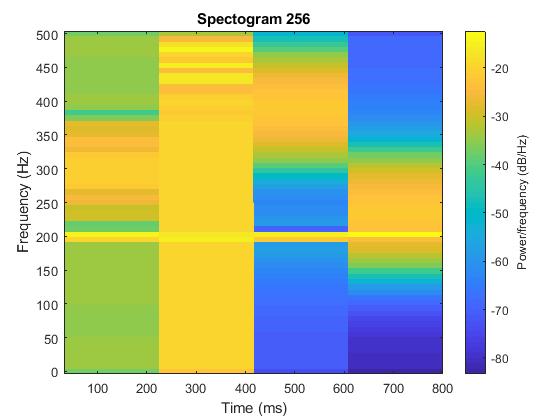


w1 = hamming(256);
figure(8);
spectrogram(x3,w1,64,128,1000,'yaxis');
title('Spectogram 256');

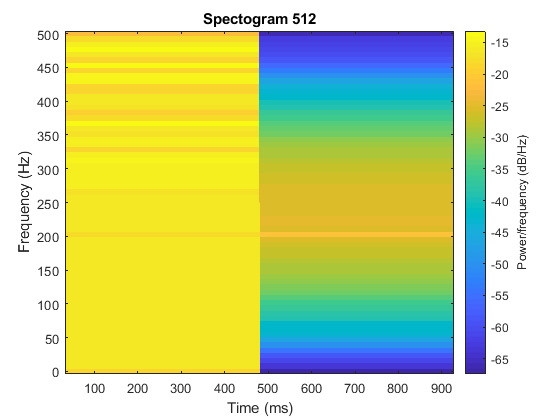

w2 = hamming(512);
figure(9);
spectrogram(x3,w2,64,128,1000,'yaxis');
title('Spectogram 512');

## Wavelet Transform

In order to find more than one order wavelet, I used the wavedec tool based on the MATLAB's suggestion. It seems that the function has taken out three levels as wavelets where their combination approximates the defined "x4" siganl.

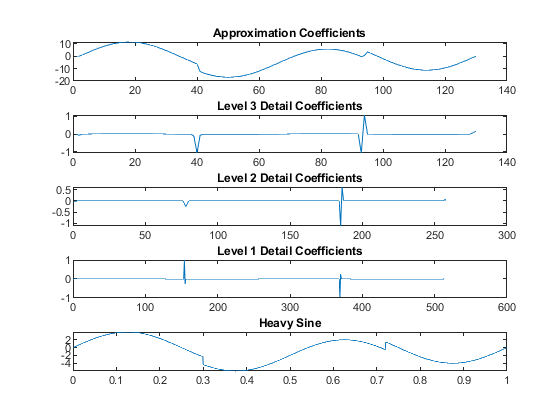

loc = linspace(0,1,2^10);
x4 = wnoise(3,10);
[c,l] = wavedec(x4,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);
figure(10)
subplot(5,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(5,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(5,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(5,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')
subplot(5,1,5)
plot(loc,x4)
title('Heavy Sine')

## Functions

function y=myconv(h,x)
M = numel(h);
L = numel(x);
N = M+L-1;
X = [x,zeros(1,M)];
H = [h,zeros(1,L)];
y = zeros(1,N);
for ii=1:N
    y(ii)=0;
    for jj=1:L
        if (ii-jj+1 >0)
            y(ii)= y(ii) + X(jj) * H(ii - jj + 1);
        end
    end
end
end